clc;
clear all;
close all;
pause('off');

# **Adaptive Controls**

# **Project Part 2 (Motor Control)**

# **Japnit Sethi**

**Objective:** The purpose of the project is to design a model reference adaptive controller for a DC motor drive, which accounts for the presence of an unknown deadzone in the power electronincs, so that the approximate velocity tracking may be achieved without knowledge of motor, load or deadzone parameters.

Dynamics of the **brush-commutated permanent-magent DC motor** turning an inertial load are described by:

$J\ldotp \frac{d}{\mathrm{d}t}\omega \;=-B\ldotp \omega \left(t\right)\;+K\ldotp i\left(t\right)$                             -   **(1)**

$L\ldotp \frac{d}{\mathrm{d}t}i\;=-K\ldotp \omega \left(t\right)\;-R\ldotp i\left(t\right)+v\left(t\right)$                    -   **(2)**

where, $\omega \left(t\right)$ is the mechanical state variable (angular velocity) **[INPUT]**

            $i\left(t\right)$ is the electrical state variable (armature current)

            $v\left(t\right)$ is the input to the motor terminals (armature voltage) [**OUTPUT**]

            J (inertia) and B (viscious friction) are** unknown constant mechanical parameters**

            L (armature inductance), R (armature Resistance) and K (motor constant) are **unknown constant electrical parameters**

Each of the unknowns J, B, L, R and K are known to be **strictly positive**

The signal $v_d \left(t\right)$ is designed such that if v(t) = $v_d \left(t\right)$, the output velocity $\omega \left(t\right)$ tracks a desired velocity signal $\omega_d \left(t\right)$ provided as the output of a reference model. The **only measurement of the plant response available to the control system is the output **$\omega \left(t\right)$ (i.e. $i\left(t\right)\;\textrm{and}\;v\left(t\right)$are not available). The desired output is specified to be:


$$\omega_d \left(t\right)=10\cdot \sin \left(2t\right)$$


but the choice of reference model (and corresponding reference signal $r\left(t\right)$) is not specified.

    For the purposes of plant simulation, the true values of the **unknown motor and load parameters** are:

J = 0.0026, B = 0.00057, L = 0.0045, R = 0.5, K = 0.56

## **Full Output Feedback System**

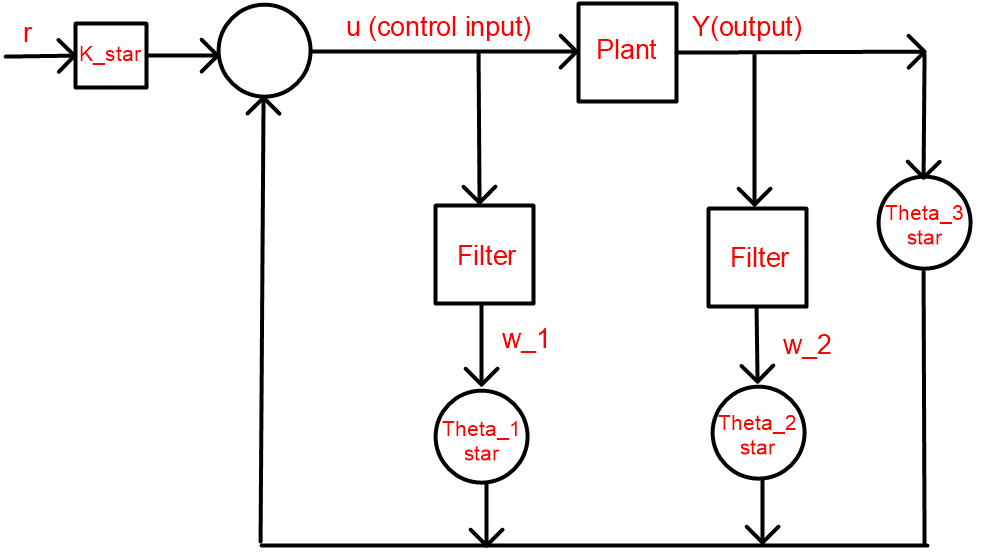

We have a **second order system**, with a relative degree 2 (resulting in 2 filters w1 and w2)so we are implementing as stated on Pg. 373. in Section 6.4 (Table 6.2) of the "Adaptive Control Notes"

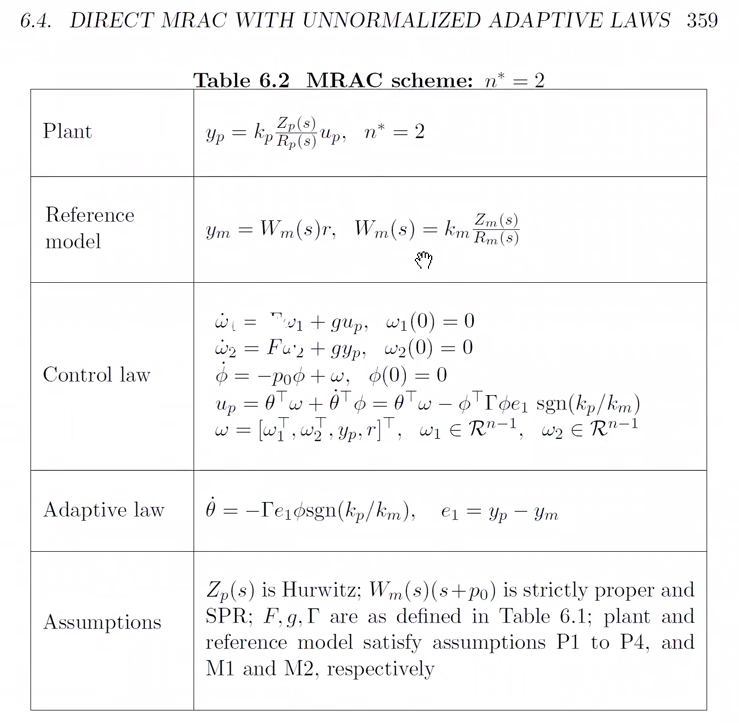

$G_p \left(s\right)=\frac{k}{s^2 +a_1 \cdot s+a_2 \;}$, This is Transfer function for our **Plant** (2nd order system)

$G_r \left(s\right)=\frac{{\omega_n }^2 }{s^2 +{2\cdot \zeta \cdot \omega }_n \cdot s+{\omega_n }^2 \;}$, This is Transfer Function for our **Reference System**

$w_1 =\frac{1}{s+\alpha }\cdot u$  , $w_1 =\frac{1}{s+\alpha }\cdot y$, These are our 2 filters $w_1$ and $w_2$

$u=\overset{\star }{\theta_0 } \cdot r\;+\overset{\star }{\theta_1 } \cdot w_1 +\overset{\star }{\theta_2 } \cdot y+\overset{\star }{\theta_3 } \cdot w_2$, This is our controller u

**WHAT WE LEARNED FOR APPLICATION IN REALITY:**

**NOTE:**  In reality we will never have the star values, star values are usually used to compute and plot the lyapunov function and thus eventhough we would be able to implement Adaptive controller, we would not be able to plot the lyapunov function for it.

## **Full Output Feedback**

## **System Parameters**

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%------ True value of Motor and Load parameters -----%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
J = 0.0026;
B = 0.00057;
R = 0.5;
K = 0.56;

% If we want to reduce the system to a 1st order system
% We can assume L very small, and thus approximately 0 
L = 0.0045;  

% To simulate Second Order system we would uncomment the above
% and not assume L to be 0
% Also uncomment the Full Second Order Subsystem in the Simulink Model !!

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%------ True value of Unknown Deadzone parameters -----%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
m = 2;
b_r = 0.8;
b_l = -1.2;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%------ Definition of Astar and Bstar, 2nd Order System -----%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
astar1 = -((K^2 + R*B)/J*L);  
astar2 = -((B/J) + (R/L));   
bstar = K/(J*L);             

Astar = [0, 1; astar1, astar2];
Bstar = [0; bstar]; 
% In reality Bstar = [0; bstar]; is a vector but we define it as a scalar
% for ease !!

% Astar = [-B/J K/J; -K/L R/L];
% bstar = [0; 1/L];
% cstar = [1 0];
% plant = ss(Astar, bstar, cstar, 0);
% filter = tf([1 p0], 1);
% plantbar = series(filter, plant);
% [Astarbar, bstarbar, cstarbar, dstarbar] = ssdata(plantbar);


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%------ Constant Reference Inputs, Full 2nd Order (Output Feedback, Preferred Approach) -----%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
zeta = .3;
omegan = 7;
ar1 = -omegan^2;
ar2 = -2*zeta*omegan;
br = 10;

Ar = [0 1; ar1 ar2];
Br = [0; br];


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%------ Adaptive Parameters (gamma_x and gamma_r), 2nd Order System -----%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
Tx_star1 = (ar1 - astar1)/Bstar(2,1);     % Tx_star1 = (ar1 - astar1)/delta; 
Tx_star2 = (ar2 - astar2)/Bstar(2,1);    % Tx_star2 = (ar2 - astar2)/delta;
Tx_star = [Tx_star1; Tx_star2];
Tr_star = Br(2,1)/Bstar(2,1);           % tr_star = br/bstar; 

Gam_x = [.1 0; 0, .1];
Gam_r = .1;

Q = [1, 0; 0, 1];
P = lyap(Ar', Q);
% Splitting P into two halves P = [P1, P2]
P1 = P(:, 1);
P2 = P(:, 2);
% Note: lyap(A, Q) solves the Lyapunov matrix Equation: A*X + X*A' + Q = 0;
% But our Lyapunove equation is A'P + PA + Q = 0, So we will use lyap(A', Q)


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%------ Projection Algorithm Stuff  -----%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% So when the vel_norm > th_max value, the saturation would kick and give
% us the saturated vel_norm2 [Those 2 in the adaptive subsystem]
th_max = 1; % Smaller value of th_max is moving my convF closer to > 0
eps_th = .1;
% Note: If we increase epsilon (eps_theta)

% So my th_max needs to be greater than norm(theta)-:{distance of theta star from
% origin}, so that the theta star is always withing the convex set (which is basically a circle with the_max as it's radius)
theta = [Tx_star; Tr_star];
if norm(theta) < th_max
    disp('Theta star is within the convex state')
end

Theta star is within the convex state


% Note: We are looking at the convex F for Theta = theta_star
% I want convex F to be < 0, because if convex F > 0 then it means that the
% theta_star is outside of the set and that means our PROJECTION algo is
% not going to work
convF = (theta'*theta - th_max^2)/(eps_th*th_max^2)

convF = -9.9999


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%------ Initial Conditions, Full 2nd Order (Output Feedback, Preferred Approach) -----%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%         
linp = 1;
Lambda = -1;
p0 = 1; % Filter to define the phi

Gam = eye(4); % [1 0 0 0;0 1 0 0;0 0 1 0;0 0 0 1];
lambda_star=1;

w10 = 0;
w20 = 0;
phi0 = [0; 0; 0; 0];

om0=0; cur0=0;
X0=[om0;cur0]; Xr0=X0; 
e0 = X0 - Xr0;
theta0 = [0 ; 0 ; 0; 0];

%V0 = e0'*P*e0 + abs(bstar)*(thx0 - tx_star)'*inv(Gam_x)*(thx0 - tx_star) + ...
%                abs(bstar)/gam_r*(thr0 - tr_star)^2;


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%------ Extracting Data from Simulink to Workspace -----%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
out = sim('AdaptiveControlsProjectPart2_Sethi');                 % Reduced 1st order system and 2nd order

% Just change the simulink blocks used for each system


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%------ Variable Assignment -----%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%------ Full, 2nd Order System (Output Feedback, Preferred Approach) -----%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
tout = out.tout;
y = out.y;

yr = out.yr;

xd = out.xd;

u = out.u; % Controller

theta = out.theta;
th_r = theta(:,1);
th_w1 = theta(:,2);
th_y = theta(:,3);
th_w2 = theta(:,4);

% Error_ref1 = yr1 - xd; 
% Error_ref2 = yr2 - dxd; 
% Error_ref = [Error_ref1, Error_ref2];
% 
% % For 2nd Order System:
Error = y - yr;
% Error2 = y2 - yr2;
% Error = [Error1, Error2];

% V1 = out.V1;
% V2 = out.V2;
% V3 = out.V3;

## **Checks**

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%------ Lyapunov Function Stability check -----%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% V1fail = 0;
% V2fail = 0;
% V3fail = 0;
% for i = 1:(length(V1)-1)
%     if (V1(i+1) - V1(i))>1e-8
%         V1fail = V1fail + 1;
%     end
%     if (V2(i+1) - V2(i))>1e-8
%         V2fail = V2fail + 1;
%     end
%     if (V3(i+1) - V3(i))>1e-8
%         V3fail = V3fail + 1;
%     end
% end
% 
% V1fail
% V2fail
% V3fail
% 
% 
% if V1fail == 0
%     disp('V1 Passed')
% else
%     disp('V1 failed')
% end
% 
% if V2fail == 0
%     disp('V2 Passed')
% else
%     disp('V2 failed')
% end
% 
% if V3fail == 0
%     disp('V3 Passed')
% else
%     disp('V3 failed')
% end

% eV = abs(V1 - V2);
% eVavg = mean(eV)

## Plots

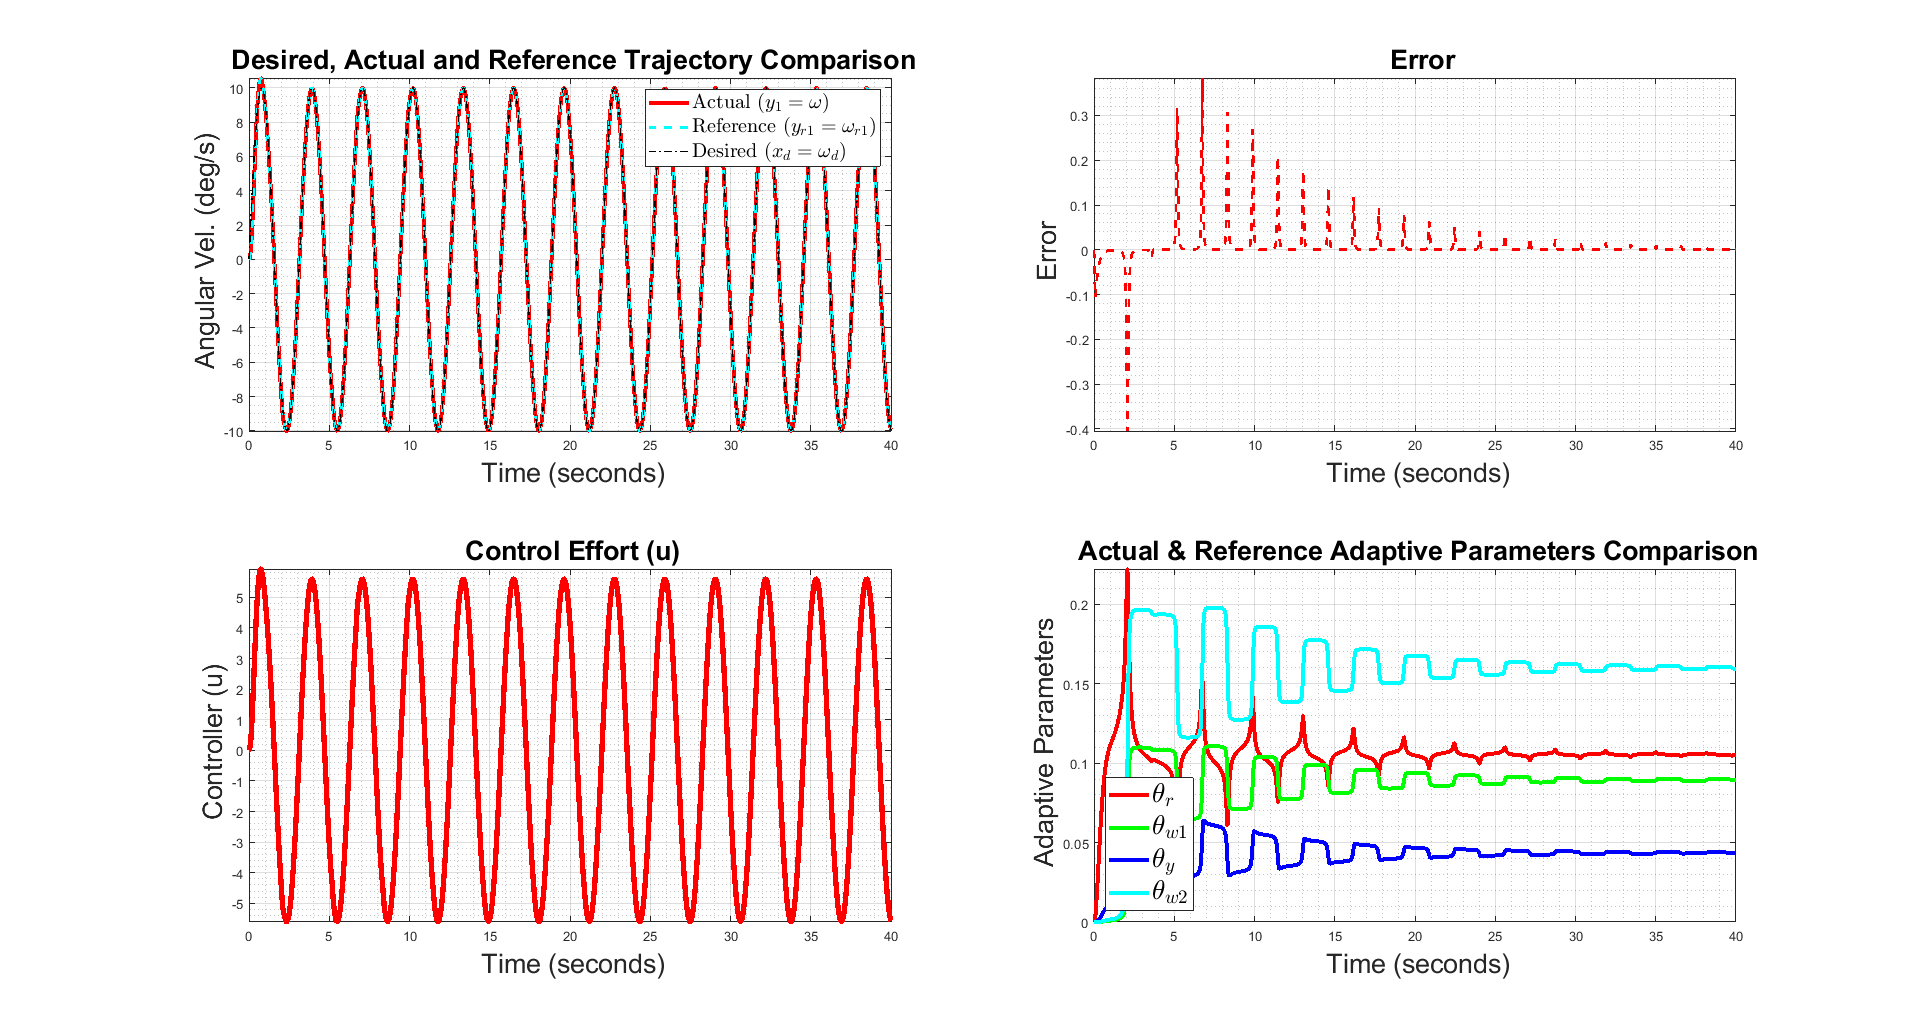

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%------ Desired, Reference and Actual Trajectory(Omega) -----%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

figure()
subplot(2,2,1)
plot(tout, y, 'LineWidth', 3, 'LineStyle', '-', 'Color', 'r');    
hold on
grid on
grid minor
axis tight
plot(tout, yr, 'LineWidth', 2, 'LineStyle', '--', 'Color', 'c');   
plot(tout, xd, 'LineWidth', 1, 'LineStyle', '-.', 'Color', 'k'); 
% plot(tout, dxd, 'LineWidth', 2, 'Color', 'b');                      % For Full 2nd Order System
lgd = legend('Actual ($y_1 = \omega$)', 'Reference ($y_{r1} = \omega_{r1}$)', 'Desired ($x_d = \omega_d$)', 'interpreter', 'latex'); % For Full 2nd Order System
lgd.FontSize = 15;
xlabel('\fontsize{20} Time (seconds)', 'interpreter', 'tex'); 
ylabel('\fontsize{20} Angular Vel. (deg/s)', 'interpreter', 'tex');  % For Full 2nd Order System
title('\fontsize{20} Desired, Actual and Reference Trajectory Comparison', 'interpreter', 'tex');
hold off
% % In order to maximize the figure window in Windows
% set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

%%%%%%%%%%%%%%%%%%%%
%------ Error -----%
%%%%%%%%%%%%%%%%%%%%

subplot(2,2, 2)
plot(tout, Error, 'LineWidth', 2, 'LineStyle', '--', 'Color', 'r');        % For Full 2nd Order System
hold on
grid on
grid minor
axis tight
% plot(tout, Error2, 'LineWidth', 4, 'LineStyle', '--', 'Color', 'c');        % For Full 2nd Order System
% plot(tout, Error_ref1, 'LineWidth', 4, 'LineStyle', '-.', 'Color', 'k');    % For Full 2nd Order System
% plot(tout, Error_ref2, 'LineWidth', 4, 'LineStyle', '-.', 'Color', 'b');    % For Full 2nd Order System
% xlim([0, max(t)]); 
% ylim([-2 2]);
% lgd = legend('Error1 ($e_1 = x_1 - x_{r1}$)', 'Error2 ($e_2 = x_2 - x_{r2}$)',...
%     'Error reference 1 ($e_{r1} = x_{r1} - x_d$)', 'Error reference 2 ($e_{r2} = x_{r2} - x_d$)', 'interpreter', 'latex'); % For Full 2nd Order System
% lgd.FontSize = 15; lgd.Location = 'southeast';
xlabel('\fontsize{20} Time (seconds)', 'interpreter', 'tex'); 
ylabel('\fontsize{20} Error', 'interpreter', 'tex'); 
title('\fontsize{20}  Error', 'interpreter', 'tex');
hold off
% % In order to maximize the figure window in Windows
% set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%------ Reference and Actual Adaptive Parameters -----%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Take care of the oscillation 

% figure()
% subplot(1,2, 1)
subplot(2,2, 4)
plot(tout, th_r, 'LineWidth', 3, 'LineStyle', '-', 'Color', 'r');      
hold on
grid on
grid minor
axis tight
plot(tout, th_w1, 'LineWidth', 3, 'LineStyle', '-', 'Color', 'g');      
plot(tout,th_y, 'LineWidth', 3, 'LineStyle', '-', 'Color', 'b');
plot(tout,th_w2, 'LineWidth', 3, 'LineStyle', '-', 'Color', 'c');
% y1 = yline(Tx_star1,'--','$(Txstar)_1$', 'interpreter', 'latex','LineWidth',2);
% y2 = yline(Tx_star2,'--','$(Txstar)_2$', 'interpreter', 'latex','LineWidth',2);
% y3 = yline(Tr_star,'--','Trstar','LineWidth',2);
% y1.FontSize = 20; y2.FontSize= y1.FontSize; y3.FontSize = y1.FontSize;
lgd = legend('$\theta_{r}$', '$\theta_{w1}$', '$\theta_{y}$', '$\theta_{w2}$', 'interpreter', 'latex');
lgd.FontSize = 20; lgd.Location = 'southwest';
xlabel('\fontsize{20} Time (seconds)', 'interpreter', 'tex'); 
ylabel('\fontsize{20} Adaptive Parameters', 'interpreter', 'tex'); 
title('\fontsize{20} Actual & Reference Adaptive Parameters Comparison', 'interpreter', 'tex');
hold off
% % In order to maximize the figure window in Windows
% set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);
% 
% % subplot(1,2, 2)
% % plot(tout,dthx, 'LineWidth', 3, 'LineStyle', '-.', 'Color', 'k'); 
% % hold on
% % grid on
% % grid minor
% % axis tight
% % plot(tout,dthr, 'LineWidth', 3, 'LineStyle', '-.', 'Color', 'c');
% % % yline(10,'--','Max limit for u','LineWidth',2);
% % % yline(-10,'--','Min limit for u','LineWidth',2);
% % lgd = legend('$\dot{\theta_x}$', '$\dot{\theta_r}$', 'interpreter', 'latex');
% % lgd.FontSize = 30; lgd.Location = 'southwest';
% % xlabel('\fontsize{20} Time (seconds)', 'interpreter', 'tex'); 
% % ylabel('\fontsize{20} Adaptive Parameters', 'interpreter', 'tex'); 
% % title('\fontsize{20} Actual & Reference Adaptive Parameters Comparison', 'interpreter', 'tex');
% % hold off
% % % In order to maximize the figure window in Windows
% % set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);
% 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%------ Controller (u) -----%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% figure()
subplot(2,2,3)
plot(tout, u, 'LineWidth', 4, 'Color', 'r');      
hold on
grid on
grid minor
axis tight    
% xlim([0, max(t)]); 
% ylim([-12 12]);
xlabel('\fontsize{20} Time (seconds)', 'interpreter', 'tex'); 
ylabel('\fontsize{20} Controller (u)', 'interpreter', 'tex'); 
title('\fontsize{20} Control Effort (u)', 'interpreter', 'tex');
hold off
% In order to maximize the figure window in Windows
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

% 
% % %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% % %------ Lyapunov Function Comparison -----%
% % %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% % Lyapunov functions should be monotonically decreasing
% 
% % subplot(1,2,2)
% subplot(2,2,4)
% plot(tout, V1, 'LineWidth', 4, 'LineStyle', '--', 'Color', 'r'); 
% hold on
% grid on
% grid minor
% plot(tout, V2, 'LineWidth', 3, 'LineStyle', '-.', 'Color', 'k'); 
% plot(tout, V3, 'LineWidth', 2, 'Color', 'b'); 
% % ylim([-12 12]);
% lgd = legend('V1', 'V2', 'V3', 'interpreter', 'tex');
% lgd.FontSize = 20;
% xlabel('\fontsize{20} Time (seconds)', 'interpreter', 'tex'); 
% ylabel('\fontsize{20} Lyapunov Function V(e, \theta_x, \theta_r)', 'interpreter', 'tex'); 
% title('\fontsize{20} Lyapunov Function Comparison', 'interpreter', 'tex');
% hold off
% 
% % In order to maximize the figure window in Windows
% set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);